# Linear Control Design II - Group Work Problem Module 17

## **Description**

The dynamics of a wind turbine operating in the full load region reads


$$J_r\dot{\omega}_r = \frac{1}{2}\rho A R \mathrm{CP}(\beta,\lambda) \frac{v^2}{\lambda} - K_{d}\theta - B_{d}\left(\omega_r - \frac{\omega_g}{N_g}\right)$$



$$J_g\dot{\omega}_g = \frac{K_{d}}{N_g}\theta + \frac{B_{d}}{N_g}\left(\omega_r - \frac{\omega_g}{N_g}\right) - T_g$$



$$\dot{\theta} = \omega_r - \frac{\omega_g}{N_g}$$



$$y_1 = \omega_r$$



$$y_2 = P_e = \omega_g T_g$$


where all quantities of interest are defined Group work Module 1. Based on the operating point and linearized model determined in Module 9 P1 and P2 address the following problems.

## Problems

**P1    **Set the generator torque to its constant operating point, $T_g = T_{g,OP}$. Under the assumption that the system state is fully accessible (i.e. all state variables are available to the controller), design a discrete time full state feedback controller with integral action that uses the pitch angle $\beta$ to regulate the rotor angular speed $\omega_r$ to its nominal value $\omega_{r,OP}$ despite variations in wind speed. The controller should assign eigenvalues such that 

- the settling time of $\omega_r$ to step changes in wind speed of $\pm2\;\mathrm{m/s}$ is between 0.5 and 1 second

- the response of $\omega_r$ to step changes in wind speed is not critically damped

% 
load('relevantWindTurbineParameters.mat')
load('LinearModel.mat')
TIME_SIM = 25;

Dv = 2; %[m/s]

% adapter the system to SISO
Bb = Bb(:,1);
Cc0 = Cc; % backup
Cc = Cc(1,:);
Dd = Dd(:,1);

% assess asymptotical stability 
lbd = eig(Aa)

lbd =   -0.2071 + 0.0000i
  -0.6797 +13.6692i
  -0.6797 -13.6692i


### Discretization

tau = 1/abs(lbd(1))

tau =        4.8291


% natural frequency
wn = sqrt(real(lbd(2))^2+imag(lbd(2))^2)

wn =        13.686


% damping ratio
z = -real(lbd(2))/wn

z =      0.049661


T_1 = tau/10

T_1 =       0.48291


T_2 = 2*pi/wn/10

T_2 =      0.045909


T_3 = 0.5/5/10

T_3 =          0.01


Ts = min([T_1,T_2,T_3])

Ts =          0.01


[Ff, Gg] = c2d(Aa,Bb,Ts)

Ff =     0.9960    0.0000   -0.1451
    2.0182    0.9792  165.8303
    0.0099   -0.0001    0.9907


Gg =    -0.0110
   -0.0097
   -0.0001


### Integral part

Fau = [Ff zeros(size(Ff,1),size(Cc,1));
      -Cc*Ts eye(size(Cc,1))]

Fau =     0.9960    0.0000   -0.1451         0
    2.0182    0.9792  165.8303         0
    0.0099   -0.0001    0.9907         0
   -0.0100         0         0    1.0000


Gau = [Gg;
       zeros(size(Cc,1), size(Gg,2))]

Gau =    -0.0110
   -0.0097
   -0.0001
         0


% assess controllability
Mc = ctrb(Fau,Gau);
if rank(Mc) == rank(Fau)
    disp('The system is controllable')
else
    disp('The system is not controllable')
end

The system is controllable


### Design Fullstate Feedback Controller

% Desired characteristics for the closed loop system
% make damp ratio with zeta = 0.8

% settling time should be between 0.5-1s
% settling time ts~4.6/(wn*zeta)

% four eigenvalues are needed; 3 for original system, 1 for integrator

% dominant eigenvalue
Tsettling = 0.75;
zeta_cl_1 = 0.65;
wn_cl_1 = 4/(Tsettling*zeta_cl_1);
% corresponding eigenvalues
alpha_1 = -wn_cl_1*zeta_cl_1;
beta_1 = sqrt(wn_cl_1^2-alpha_1^2);

% the other eigenvalues
wn_cl_2 = wn_cl_1*1.2; % bit faster than the dominant
zeta_cl_2 = 0.8;
alpha_2 = -wn_cl_2*zeta_cl_2;
beta_2 = sqrt(wn_cl_2^2-alpha_2^2);

% collect closed loop eigenvalues
lambda_ct_des = [alpha_1+1i*beta_1 alpha_1-1i*beta_1 alpha_2+1i*beta_2 alpha_2-1i*beta_2]

lambda_ct_des =   -5.3333 + 6.2354i  -5.3333 - 6.2354i  -7.8769 + 5.9077i  -7.8769 - 5.9077i


% discrete eigenvalues
lambda_dt_des = exp(lambda_ct_des*Ts)

lambda_dt_des =    0.9462 + 0.0591i   0.9462 - 0.0591i   0.9226 + 0.0546i   0.9226 - 0.0546i


K1 = acker(Fau,Gau,lambda_dt_des);
K_FSF = K1(1:3)

K_FSF =   -20.4400    0.1119  -62.8482


Ki = -K1(4)

Ki =       -30.222


% verify eigenvalues
1/Ts*log(eig(Fau - Gau*K1))

ans =   -7.8769 + 5.9077i
  -7.8769 - 5.9077i
  -5.3333 + 6.2354i
  -5.3333 - 6.2354i


**P2    **Implement the open loop linear system and the designed control system in Simulink. Evaluate the performance of your controller against the given requirements in response to wind speed step changes of $\pm 2\, \mathrm{m/s}$.

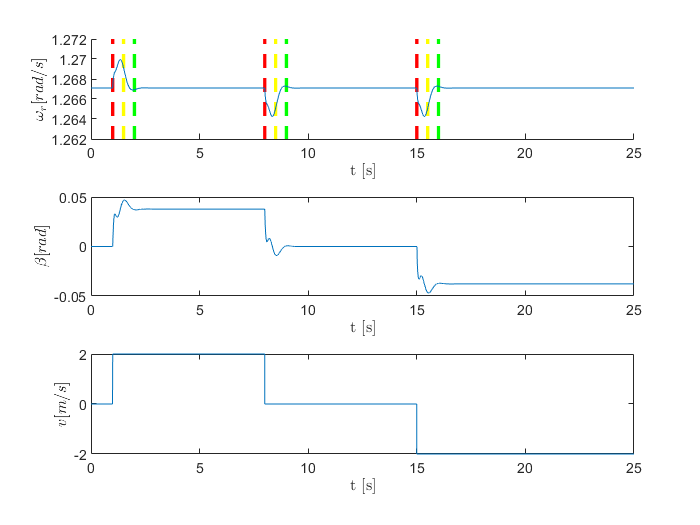

% 
STEP_SIZE = Ts/50;

% disturbance input
v_in = [zeros(1,floor(1/STEP_SIZE)) Dv*ones(1,floor(7/STEP_SIZE)) zeros(1,floor(7/STEP_SIZE)) -Dv*ones(1,floor(7/STEP_SIZE))];
t = 0:STEP_SIZE:TIME_SIM;
pad = length(t)-length(v_in);
v_in = [v_in -Dv*ones(1, pad)];

% Find indiceses of windspeed changes and +4s and +6s (for plots)
stCh = find(diff(v_in) ~= 0);
ch1 = t(stCh(1));
ch14 = t(stCh(1)+floor(0.5/STEP_SIZE));
ch16 = t(stCh(1)+floor(1/STEP_SIZE));
ch2 = t(stCh(2));
ch24 = t(stCh(2)+floor(0.5/STEP_SIZE));
ch26 = t(stCh(2)+floor(1/STEP_SIZE));
ch3 = t(stCh(3));
ch34 = t(stCh(3)+floor(0.5/STEP_SIZE));
ch36 = t(stCh(3)+floor(1/STEP_SIZE));
w_OPup = w_OP*1.01;
w_OPlow = w_OP*0.99;


[~,~,yout] = sim('Myp2LinearIntegral.slx', [0 TIME_SIM], [], [t' v_in']);

figure 

subplot(3,1,1)

line([ch1 ch1],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
hold on
line([ch14 ch14],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch16 ch16],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch2 ch2],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch24 ch24],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch26 ch26],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch3 ch3],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch34 ch34],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch36 ch36],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)

plot(t,yout(:,1)) % wr
ylim([1.262 1.272])
xlabel('t [s]','Interpreter','latex')
ylabel('$\omega_r [rad/s]$','Interpreter','latex')

subplot(3,1,2)
plot(t,yout(:,3)) %u - beta
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta [rad]$','Interpreter','latex')

subplot(3,1,3)
plot(t,yout(:,2)) % v - wind speed
xlabel('t [s]','Interpreter','latex')
ylabel('$v [m/s]$','Interpreter','latex')

youtP2 = yout;
youtP2(:,2) = yout(:,2) + v_OP;
youtP2(:,3) = yout(:,3) + beta_OP;

**P3    **Implement the designed controller on the Simulink nonlinear model of the wind turbine provided in Module 10 and repeat the simulations performed in P2. Compare and discuss the performance of the control system on the linearized and nonlinear model.

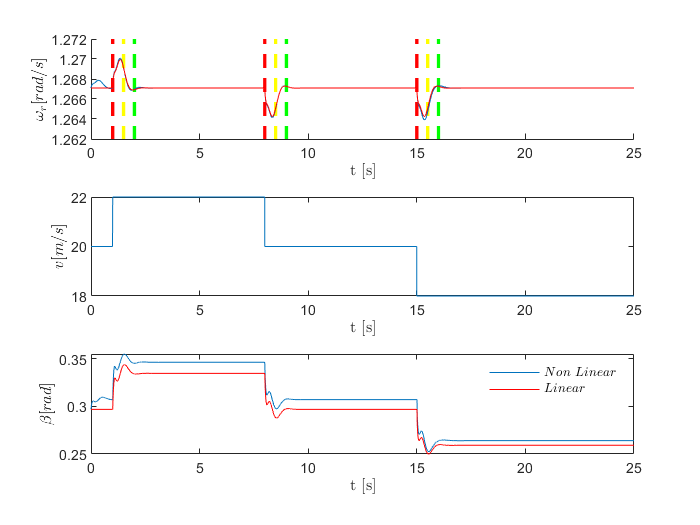

% 
v_inNonLinear = v_in + v_OP; % use the real wind speed

[~,~, yout] = sim('Myp3NLintegral.slx', TIME_SIM, [], [t' v_inNonLinear']);
youtP3 = yout;

figure
subplot(3,1,1)
line([ch1 ch1],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
hold on
line([ch14 ch14],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch16 ch16],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch2 ch2],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch24 ch24],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch26 ch26],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch3 ch3],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch34 ch34],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch36 ch36],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)

plot(t,yout(:,1))
plot(t,youtP2(:,1),'Color','r')
hold off
xlabel('t [s]','Interpreter','latex')
ylabel('$\omega_r [rad/s]$','Interpreter','latex')
ylim([1.262 1.272])

subplot(3,1,2)
plot(t,yout(:,2))
xlabel('t [s]','Interpreter','latex')
ylabel('$v [m/s]$','Interpreter','latex')

subplot(3,1,3)
plot(t,yout(:,3))
hold on
plot(t,youtP2(:,3),'Color','r')
hold off
leg1 = legend('$Non \ Linear$','$Linear$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta [rad]$','Interpreter','latex')

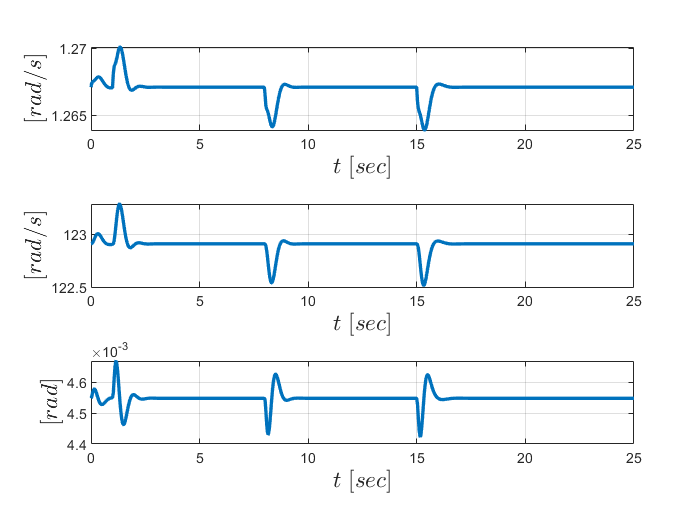

figure
subplot(3,1,1)
plot(t,states.signals.values(:,1), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$[rad/s]$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
subplot(3,1,2)
plot(t,states.signals.values(:,2), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$[rad/s]$', 'Interpreter', 'latex', 'FontSize', 14);
grid;
subplot(3,1,3)
plot(t,states.signals.values(:,3), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$[rad]$', 'Interpreter', 'latex', 'FontSize', 14);
grid;

**P4    **Since only the rotor angular velocity and the electrical power are measured the controller designed in P1 cannot be implemented in reality unless an observer is also designed to estimate the unmeasured state variable. Design a discrete time full order observer that provides the state estimates of the measured and unmeasured state variables. The estimation error dynamics should settle to zero within 0.1 and 0.2 seconds.

% The observer estimates 3 states, thus we need 3 eigenvalues
% choose a complex pair and a real eigenvalue
% the settling time should be T_settling ~ 4*tau
t_settling_obs_1 = 0.15; % settling time
tau_obs_1 = t_settling_obs_1/4;
lambda_obs_1 = -1/tau_obs_1;

% for complex pair, choose a faster response
t_settling_obs_2 = 0.1;
alpha_obs_2 = -4/t_settling_obs_2;  
zeta_obs_2 = 0.8;
wn_obs_2 = -alpha_obs_2/zeta_obs_2;
beta_obs_2 = sqrt(wn_obs_2^2 - alpha_obs_2^2);
lambda_ct_obs_des = [lambda_obs_1 alpha_obs_2+1i*beta_obs_2 alpha_obs_2-1i*beta_obs_2]

lambda_ct_obs_des =  -26.6667 + 0.0000i -40.0000 +30.0000i -40.0000 -30.0000i


lambda_dt_obs_des = exp(lambda_ct_obs_des*Ts) 

lambda_dt_obs_des =    0.7659 + 0.0000i   0.6404 + 0.1981i   0.6404 - 0.1981i


L = place(Ff', Cc0',lambda_dt_obs_des')'

L =     0.2301   -0.0098
    2.0178   16.9393
    0.0099    0.0215


% eigenvalue verify
check1 = eig(Ff-L*Cc0)

check1 =    0.7659 + 0.0000i
   0.6404 + 0.1981i
   0.6404 - 0.1981i


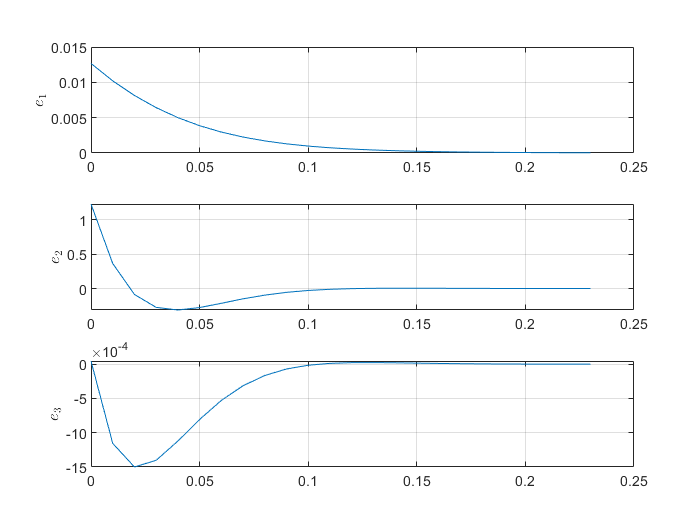

% simulate to check if observer satisfy the requirement
tP4 = 0:Ts:0.23;
xe0 = 0.1*xOP; % give zero initial guess as the deviation; have to be very small
Fe = Ff-L*Cc0;
Ge = zeros(size(Ff,1),1); % [0;0;0]
Ce = eye(size(Ff,1)); %[1 0 0;0 1 0; 0 0 1] 
De = Ge; % 0

sys = ss(Fe,Ge,Ce,De,Ts);
[e,te,~] = initial(sys,xe0);

figure
subplot(3,1,1)
plot(te,e(:,1))
ylabel('$e_1$','Interpreter','latex')
grid on
subplot(3,1,2)
plot(te,e(:,2))
ylabel('$e_2$','Interpreter','latex')
grid on
subplot(3,1,3)
plot(te,e(:,3))
ylabel('$t \ [s]$','Interpreter','latex')
ylabel('$e_3$','Interpreter','latex')
grid on

The plot above shows the estimation error zero-input response for 10% initial bias in the states estimatons.

**P5   **Implement the designed observer on the open loop linear model and evaluate its estimation performance around the operating point for step changes in pitch angle $\beta$ of $\pm 3 \;\mathrm{deg}$.

%
Mo = obsv(Aa,Cc);
rank(Mo)

ans =      3


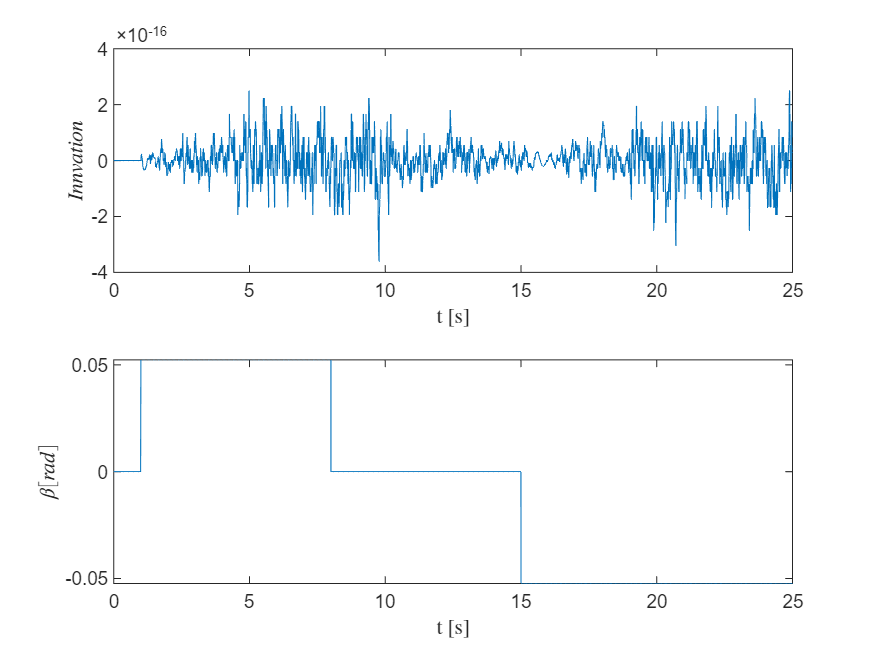

DBeta = 3*pi/180; % [rad]
beta_in = [zeros(1,floor(1/STEP_SIZE)) DBeta*ones(1,floor(7/STEP_SIZE)) zeros(1,floor(7/STEP_SIZE)) -DBeta*ones(1,floor(7/STEP_SIZE))];
pad = length(t) - length(beta_in);
beta_in = [beta_in -DBeta*ones(1,pad)];

stCh = find(diff(beta_in) ~= 0);
ch1 = t(stCh(1));
ch14 = t(stCh(1)+floor(0.5/STEP_SIZE));
ch16 = t(stCh(1)+floor(1/STEP_SIZE));
ch2 = t(stCh(2));
ch24 = t(stCh(2)+floor(0.5/STEP_SIZE));
ch26 = t(stCh(2)+floor(1/STEP_SIZE));
ch3 = t(stCh(3));
ch34 = t(stCh(3)+floor(0.5/STEP_SIZE));
ch36 = t(stCh(3)+floor(1/STEP_SIZE));
w_OPup = w_OP+0.005;
w_OPlow = w_OP-0.005;

[~,~,yout] = sim('Myp5LinearOpenLoopObserver', TIME_SIM, [], [t' beta_in']);
CcO=Cc0;
% [~,~,yout] = sim('p5_linearWindTurbineModel',[0 TIME_SIM],[],[t' beta_in']);
figure
subplot(2,1,1)
plot(t,yout(:,4))
xlabel('t [s]','Interpreter','latex')
ylabel('$Innvation$','Interpreter','latex')
subplot(2,1,2)
plot(t,beta_in)
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta [rad]$','Interpreter','latex')

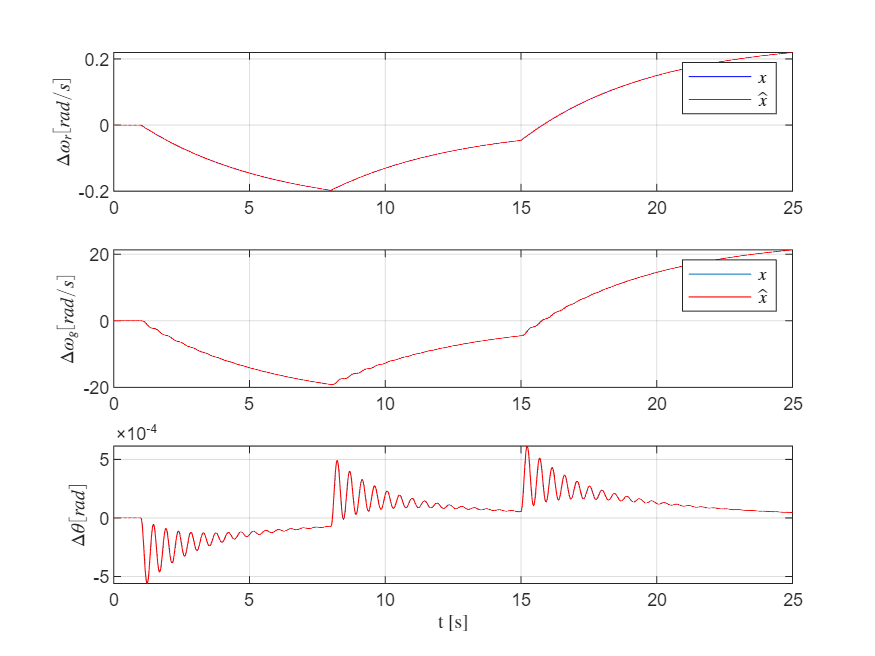

% Comparison of true and estimated states for the linear model
figure

subplot(3,1,1)
plot(t,yout(:,6),'Color','b')
hold on
plot(t,yout(:,1),'Color','r')
grid on
ylabel('$\Delta\omega_r [rad/s]$','Interpreter','latex')
hold off
leg1 = legend('$x$','$\hat{x}$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);

subplot(3,1,2)
plot(t,yout(:,7))
hold on
plot(t,yout(:,2),'Color','r')
grid on
ylabel('$\Delta\omega_g [rad/s]$','Interpreter','latex')
hold off

leg1 = legend('$x$','$\hat{x}$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);

subplot(3,1,3)
plot(t,yout(:,8))
hold on
plot(t,yout(:,3),'Color','r')
grid on
xlabel('t [s]','Interpreter','latex')
ylabel('$\Delta\theta [rad]$','Interpreter','latex')
hold off

Simulation of Non-Linear model

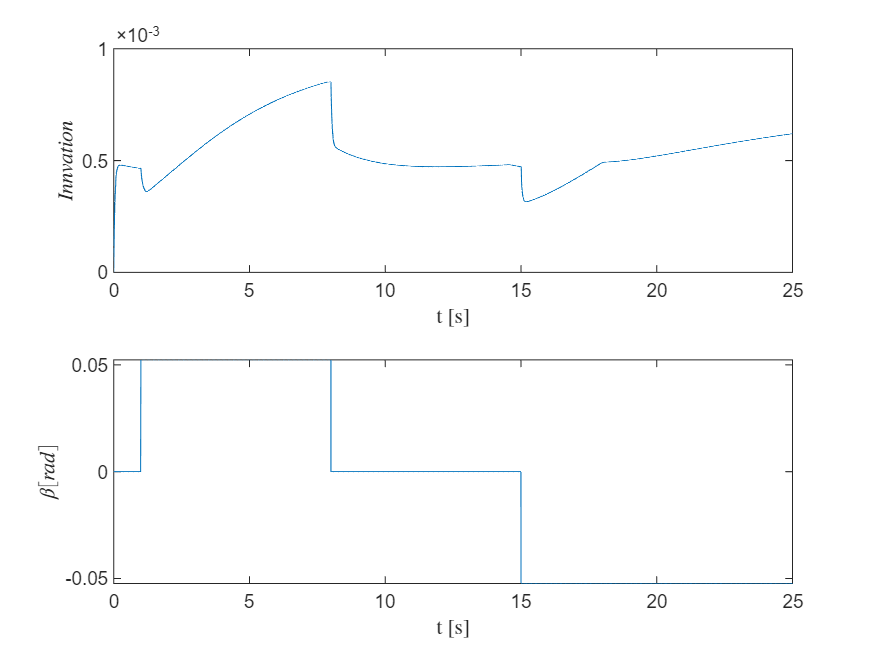

% Non-linear model
close all
[~,~,yout] = sim('Myp5NLOpenLoopObserver.slx',TIME_SIM,[],[t' beta_in']);
% yout = [xh1, xh2, xh2, inn1, inn2, w3, x1, x2, x3]
figure
subplot(2,1,1)
plot(t,yout(:,4))
xlabel('t [s]','Interpreter','latex')
ylabel('$Innvation$','Interpreter','latex')
subplot(2,1,2)
plot(t,beta_in)
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta [rad]$','Interpreter','latex')

For the non-linear system a small offset is present in the innovation

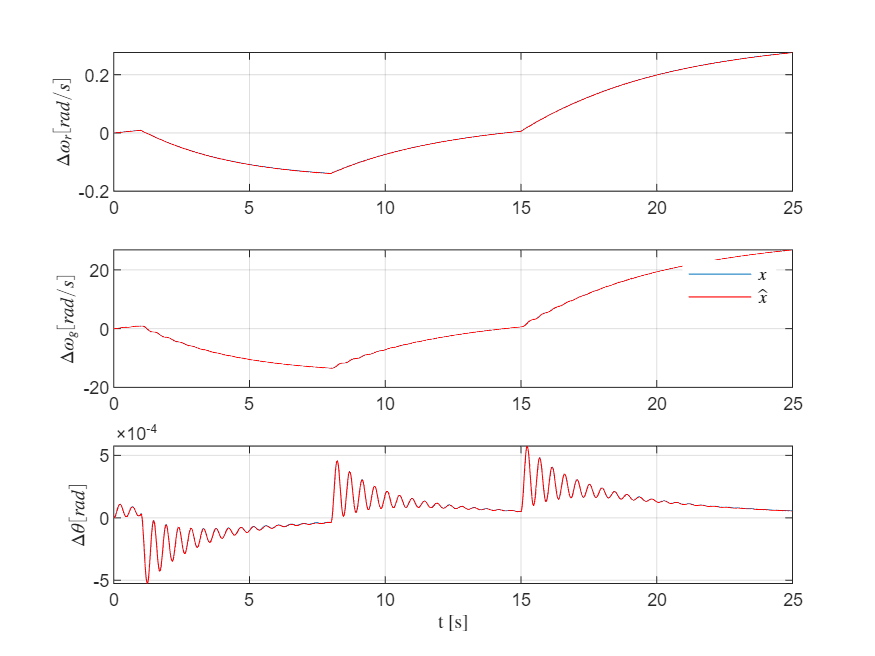

% Comparison of true and estimated states
figure

subplot(3,1,1)
plot(t,yout(:,7))
hold on
plot(t,yout(:,1),'Color','r')
grid on
ylabel('$\Delta\omega_r [rad/s]$','Interpreter','latex')
hold off

subplot(3,1,2)
plot(t,yout(:,8))
hold on
plot(t,yout(:,2),'Color','r')
grid on
ylabel('$\Delta\omega_g [rad/s]$','Interpreter','latex')
hold off

leg1 = legend('$x$','$\hat{x}$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff

subplot(3,1,3)
plot(t,yout(:,9))
hold on
plot(t,yout(:,3),'Color','r')
grid on
xlabel('t [s]','Interpreter','latex')
ylabel('$\Delta\theta [rad]$','Interpreter','latex')
hold off

**P6    **Now close the loop again around the linearized model by feeding the controller with the estimates provided by the observer and evaluate the control system performance against that obtained in P2.

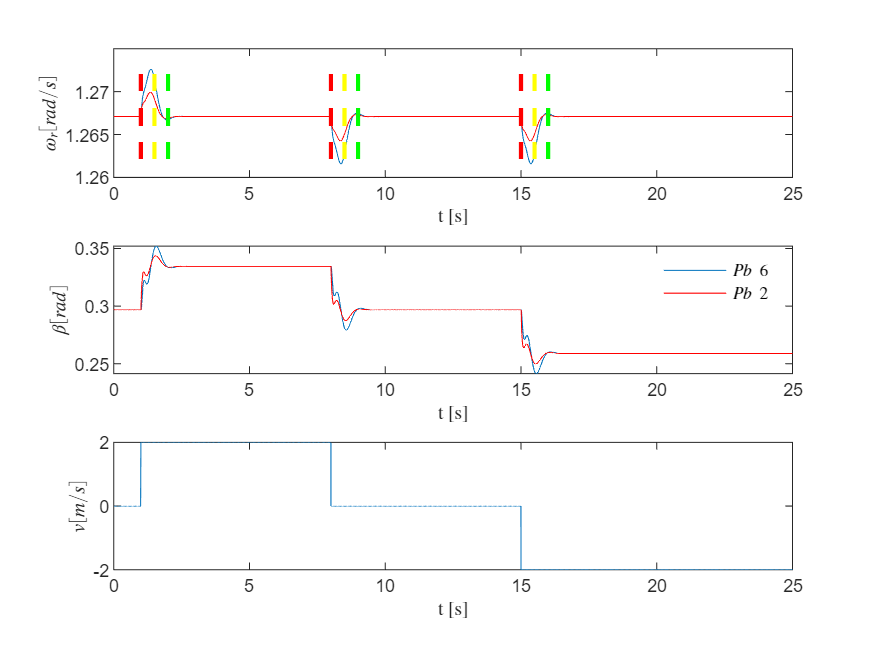

% 
close all
[~,~,yout] = sim('Myp6LinearIntegralObserverFeed.slx',TIME_SIM,[],[t' v_in']);
% Plot wr, windspeed and input
figure,
subplot(3,1,1)
plot(t,yout(:,1))
hold on
plot(t,youtP2(:,1),'Color','r')
line([ch1 ch1],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch14 ch14],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch16 ch16],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch2 ch2],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch24 ch24],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch26 ch26],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch3 ch3],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch34 ch34],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch36 ch36],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
hold off
xlabel('t [s]','Interpreter','latex')
ylabel('$\omega_r [rad/s]$','Interpreter','latex')
subplot(3,1,2)
plot(t,yout(:,3)+beta_OP)
hold on
plot(t,youtP2(:,3),'Color','r')
hold off
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta [rad]$','Interpreter','latex')
leg1 = legend('$Pb \ 6$','$Pb \ 2$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff
subplot(3,1,3)
plot(t,yout(:,2))
xlabel('t [s]','Interpreter','latex')
ylabel('$v [m/s]$','Interpreter','latex')

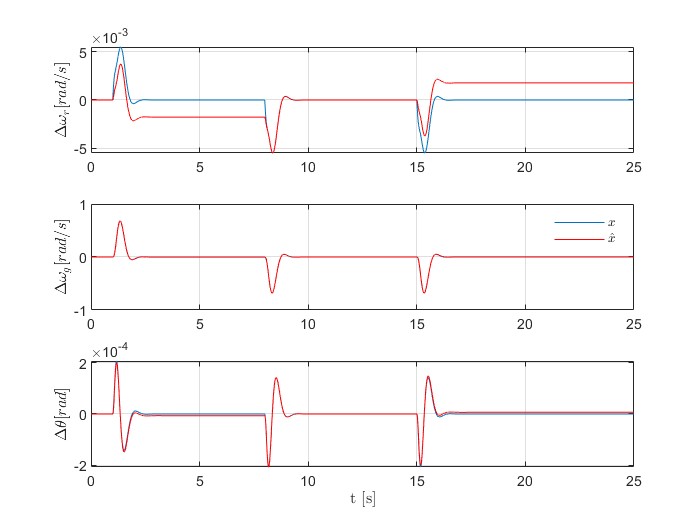

figure

subplot(3,1,1)
plot(t,yout(:,4))
hold on
plot(t,yout(:,7),'Color','r')
grid on
ylabel('$\Delta\omega_r [rad/s]$','Interpreter','latex')
hold off

subplot(3,1,2)
plot(t,yout(:,5))
hold on
plot(t,yout(:,8),'Color','r')
grid on
ylabel('$\Delta\omega_g [rad/s]$','Interpreter','latex')
hold off

leg1 = legend('$x$','$\hat{x}$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff

subplot(3,1,3)
plot(t,yout(:,6))
hold on
plot(t,yout(:,9),'Color','r')
grid on
xlabel('t [s]','Interpreter','latex')
ylabel('$\Delta\theta [rad]$','Interpreter','latex')
hold off

**P7**    Last, close the loop around the nonlinear system with the controller and observer and compare the performance against that obtained in P3

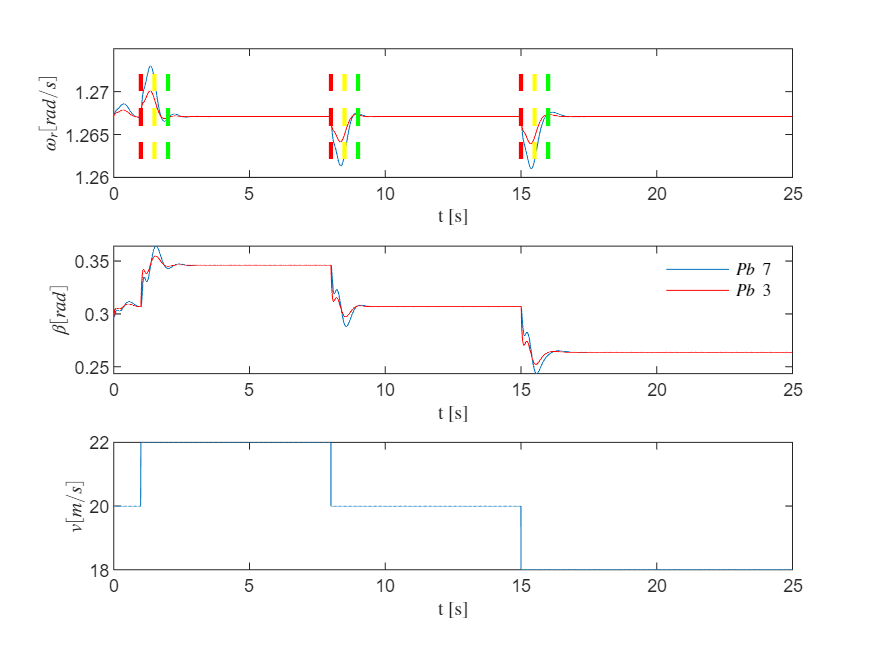

% 
[~,~,yout] = sim('Myp7NLIntegralObserverFeed.slx',TIME_SIM,[],[t' v_inNonLinear']);
% Plot wr, windspeed and input
figure,
subplot(3,1,1)
plot(t,yout(:,1))
hold on
plot(t,youtP3(:,1),'Color','r')
line([ch1 ch1],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch14 ch14],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch16 ch16],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch2 ch2],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch24 ch24],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch26 ch26],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
line([ch3 ch3],[w_OPlow w_OPup],'Color','red','LineStyle','--','Linewidth',2)
line([ch34 ch34],[w_OPlow w_OPup],'Color','yellow','LineStyle','--','Linewidth',2)
line([ch36 ch36],[w_OPlow w_OPup],'Color','green','LineStyle','--','Linewidth',2)
hold off
xlabel('t [s]','Interpreter','latex')
ylabel('$\omega_r [rad/s]$','Interpreter','latex')
subplot(3,1,2)
plot(t,yout(:,3)+beta_OP)
hold on
plot(t,youtP3(:,3),'Color','r')
hold off
leg1 = legend('$Pb \ 7$','$Pb \ 3$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta [rad]$','Interpreter','latex')
subplot(3,1,3)
plot(t,yout(:,2))
xlabel('t [s]','Interpreter','latex')
ylabel('$v [m/s]$','Interpreter','latex')

Once again the observer based full state feedback with integral action performs slightly worse though it still respects the requirements. The reasons for performance degradation can be found on the unmodelled disturbance within the observer.

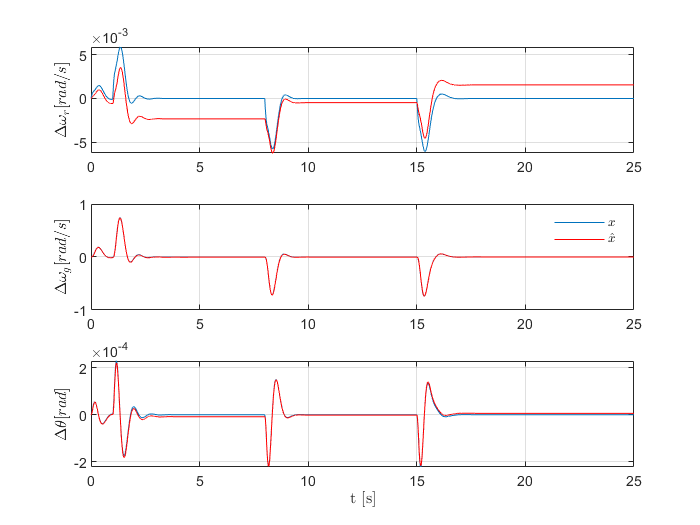

% Now compare the state estimates with the actual state

figure

subplot(3,1,1)
plot(t,yout(:,4))
hold on
plot(t,yout(:,7),'Color','r')
grid on
ylabel('$\Delta\omega_r [rad/s]$','Interpreter','latex')
hold off

subplot(3,1,2)
plot(t,yout(:,5))
hold on
plot(t,yout(:,8),'Color','r')
grid on
ylabel('$\Delta\omega_g [rad/s]$','Interpreter','latex')
hold off

leg1 = legend('$x$','$\hat{x}$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',8);
legend boxoff

subplot(3,1,3)
plot(t,yout(:,6))
hold on
plot(t,yout(:,9),'Color','r')
grid on
xlabel('t [s]','Interpreter','latex')
ylabel('$\Delta\theta [rad]$','Interpreter','latex')
hold off